# CNN MNIST Siamese network

This example shows a simple example of the DAG interface for a MNIST Siamese network. This network is a simple extension of the original MNIST network with two branches connected to a contrastive loss. This experiment shows how to run an example and visualise the network and how to use the trained network to obtain the target embedding.

## Train and plot the CNN MNIST Siamese network

The network is constructed and trained in the file `cnn_mnist_siamese`.

% Train the network
[net, info, imdb] = cnn_mnist_siamese();

cnn_train_dag: resuming by loading epoch 10


We can see the network structure using the `DagNN.print` method:

inputs = {'input_a', [28, 28, 1, 64], 'input_b', [28, 28, 1, 64], 'label', [1, 1, 1, 64]};
net.print(inputs, 'format', 'ascii', 'MaxNumColumns', 4);

   func|       layer1_a|layer2_a|       layer3_a|layer4_a|
-------|---------------|--------|---------------|--------|
   type|           Conv| Pooling|           Conv| Pooling|
 inputs|        input_a|    x1_a|           x2_a|    x3_a|
outputs|           x1_a|    x2_a|           x3_a|    x4_a|
 params|layer1f layer1b|        |layer3f layer3b|        |
    pad|              0|       0|              0|       0|
 stride|              1|       2|              1|       2|

   func|       layer5_a|layer6_a|      emb_a|       layer1_b|
-------|---------------|--------|-----------|---------------|
   type|           Conv|    ReLU|       Conv|           Conv|
 inputs|           x4_a|    x5_a|       x6_a|        input_b|
outputs|           x5_a|    x6_a|      emb_a|           x1_b|
 params|layer5f layer5b|        |emb_f emb_b|layer1f layer1b|
    pad|              0|     n/a|          0|              0|
 stride|              1|     n/a|          1|              1|

   func|layer2_b|       layer3

or we can visualise it using the matlab |digraph| function. The width of the edges corresponds to the spatial size of the variables and the color of the variable nodes (circles) corresponds to the number of channels. This can give a quick overview of the network structure (in order to be able to run this command, Matlab >R2015b is needed).

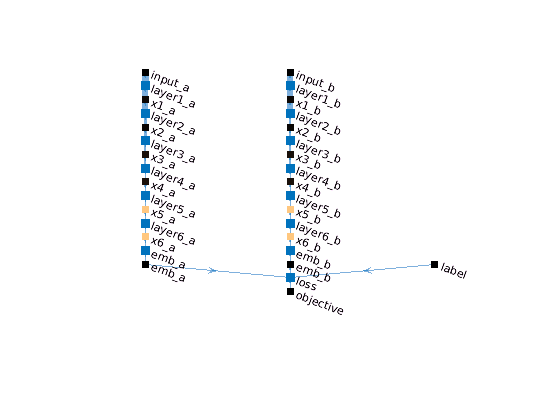

layout(net.print(inputs, 'format', 'digraph'), 'layered');

We can also easily visualise the development of training objective during training:

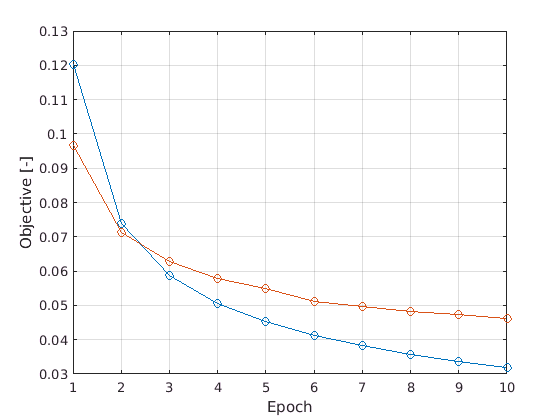

plot([[info.train.objective]; [info.val.objective]]', '-o');
xlabel('Epoch'); ylabel('Objective [-]'); grid on;

## Feature embedding

In order to use the network for the embedding only, we need to perform a surgical operation to remove the second branch of layers. In order to do that we at first create a deep copy _netEval_ of the network and then remove all layers from the second branch.

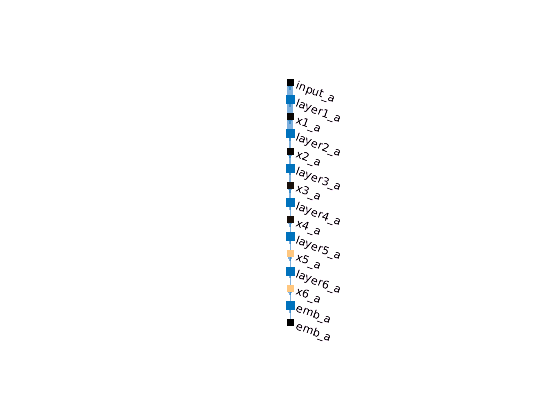

netEval = copy(net);
layerNames = {netEval.layers.name};
netEval.removeLayer([layerNames(~cellfun(@isempty, strfind(layerNames, '_b'))), 'loss']);

inputs = {'input_a', [28, 28, 1, 64]};
figure(1);
layout(netEval.print(inputs, 'format', 'digraph'), 'layered');

In order to obtain the embedding we at fisr select some subset of the testing data and evaluate it in our thinned network:

dataSel = randsample(find(imdb.images.set == 3), 1000);
dataLabel = imdb.images.labels(dataSel);
data = imdb.images.data(:,:,:,dataSel);
netEval.eval({'input_a', data});

then, obtaining the feature representation is a simple task:

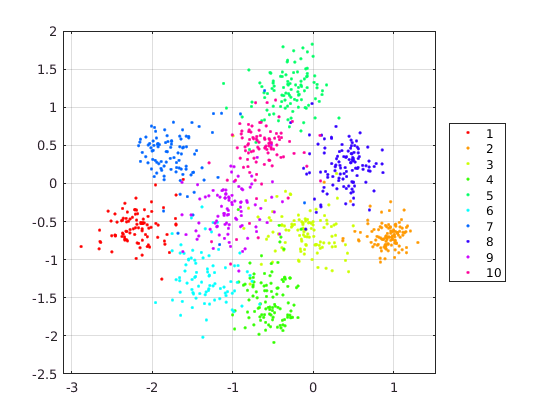

feat = squeeze(netEval.getVar('emb_a').value);
gscatter(feat(1,:), feat(2,:), dataLabel); grid on;
legend(arrayfun(@num2str, 1:10, 'UniformOutput', false), 'Location', 'EastOutside');